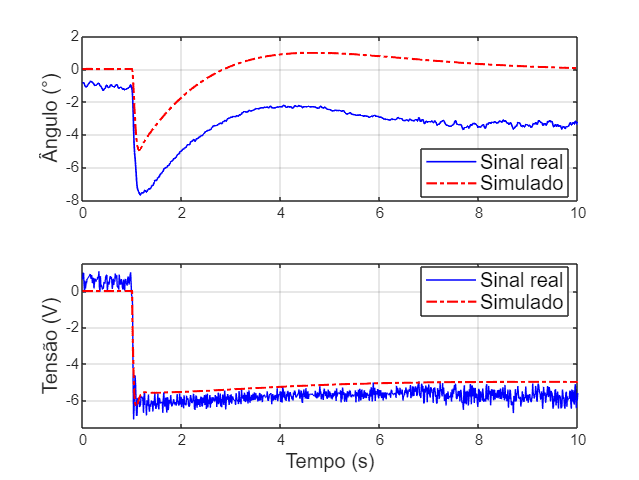

clc;
close all;

% Carregar dados do arquivo
data = load('guarda_degrau2.txt');

% Definir intervalo de tempo
inicio = 1;
final = 2600;

xInit = 0;
xFinal = 10;


tempo = data(inicio:final, 1)-20;
angulo1 = -data(inicio:final, 2)*57.296; % theta
angulo2 = data(inicio:final, 3)*57.296; % theta_dot
Xis = data(inicio:final, 4); % X
Xis_dot = data(inicio:final, 5); % X_dot
entrada = data(inicio:final, 6); % Ação de controle
disturbio = data(inicio:final, 7); % Disturbio

% Dados do Simulink
tempo_sim = out.tout;
angulo1_sim = out.yout{1}.Values.Data; % theta
angulo2_sim = out.yout{2}.Values.Data; % theta_dot
Xis_sim = out.yout{3}.Values.Data * -1; % omega
Xis_dot_sim = out.yout{4}.Values.Data * -1; % omega
entrada_sim = out.yout{5}.Values.Data; % Ação de controle
disturbio_sim = out.yout{6}.Values.Data; % Disturbio

figure;
subplot(2, 1, 1)
plot(tempo, angulo1, 'b', 'LineWidth', 1);
hold on;
plot(tempo_sim, angulo1_sim, '-.r', 'LineWidth', 1.3);
%xlabel('Tempo (s)', 'FontSize', 14)
ylabel('Ângulo (°)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
% ylim([-2.7 1.3]);
hold off;

subplot(2, 1, 2)
plot(tempo, entrada, 'b', 'LineWidth', 0.5);
hold on;
plot(tempo_sim, entrada_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 12)
ylabel('Tensão (V)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
ylim([-7.5 1.5]);
hold off;

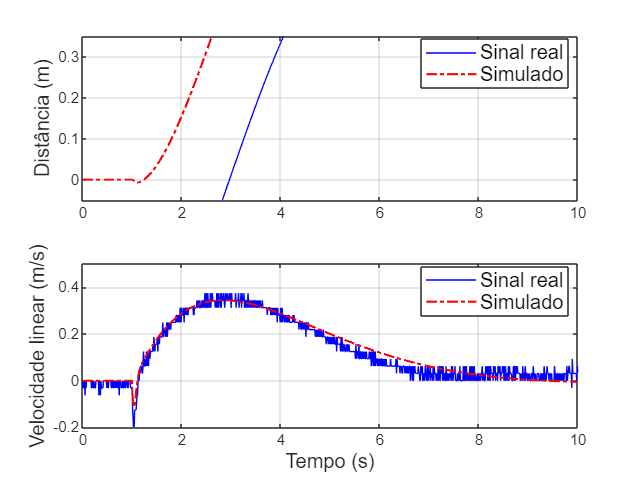


figure;
subplot(2, 1, 1)
plot(tempo, Xis, 'b', 'LineWidth', 0.5);
hold on;
plot(tempo_sim, Xis_sim, '-.r', 'LineWidth', 1.3);
%xlabel('Tempo (s)', 'FontSize', 14)
ylabel('Distância (m)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
ylim([-0.05 0.35]);
hold off;

subplot(2, 1, 2)
plot(tempo, Xis_dot, 'b', 'LineWidth', 0.5);
hold on;
plot(tempo_sim, Xis_dot_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 12)
ylabel('Velocidade linear (m/s)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
ylim([-0.2 0.5]);
hold off;

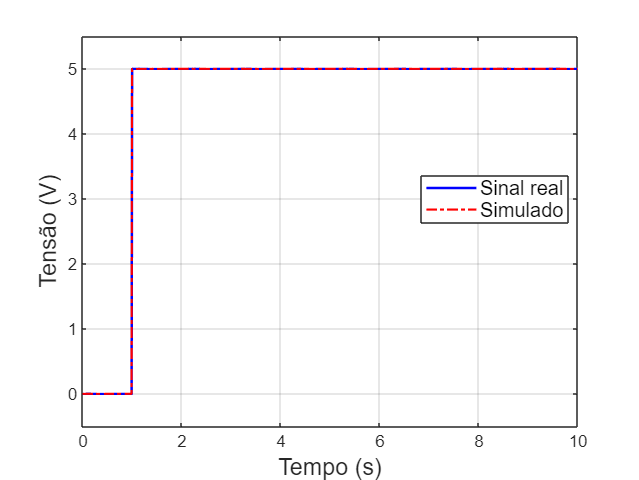


figure;
plot(tempo, disturbio, 'b', 'LineWidth', 1.5);
hold on;
plot(tempo_sim, disturbio_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 14)
ylabel('Tensão (V)', 'FontSize', 14)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
ylim([-0.5 5.5]);
hold off;